Control de Velocidad  de un Motor 

s= tf('s');
%% declaracion de las constantes 
k = 0.052516664;
B= 6.40115E-05;
L =5.33;
J=4.738e-9;
R= 39.3;
G_s= (k)/((s*L+R)*(s*J+B)+k*k)

G_s =
 
                 0.05252
  --------------------------------------
  2.525e-08 s^2 + 0.0003414 s + 0.005274
 
Continuous-time transfer function.





Ts=0.0001;
C= pid(1,0,0)

C =
 
  Kp = 1
 
P-only controller.



[num , den] = tfdata(C);
[num , den]= c2dm(num,den,Ts,'tustin')

num = 1

den = 1

Control_z= filt(num,den,Ts)

Control_z =
 
  1
 
Static gain.




[num , den] = tfdata(G_s);
[num , den]= c2dm(num,den,Ts,'zoh');
F_z= filt(num,den,Ts)

F_z =
 
  0.006947 z^-1 + 0.004454 z^-2
  -----------------------------
  1 - 1.258 z^-1 + 0.2588 z^-2
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



sistema_z= (Control_z*F_z)/(1+Control_z*F_z)

sistema_z =
 
  0.006947 z^-1 - 0.004284 z^-2 - 0.003803 z^-3 + 0.001153 z^-4
  -------------------------------------------------------------
    1 - 2.508 z^-1 + 2.095 z^-2 - 0.6547 z^-3 + 0.06812 z^-4
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



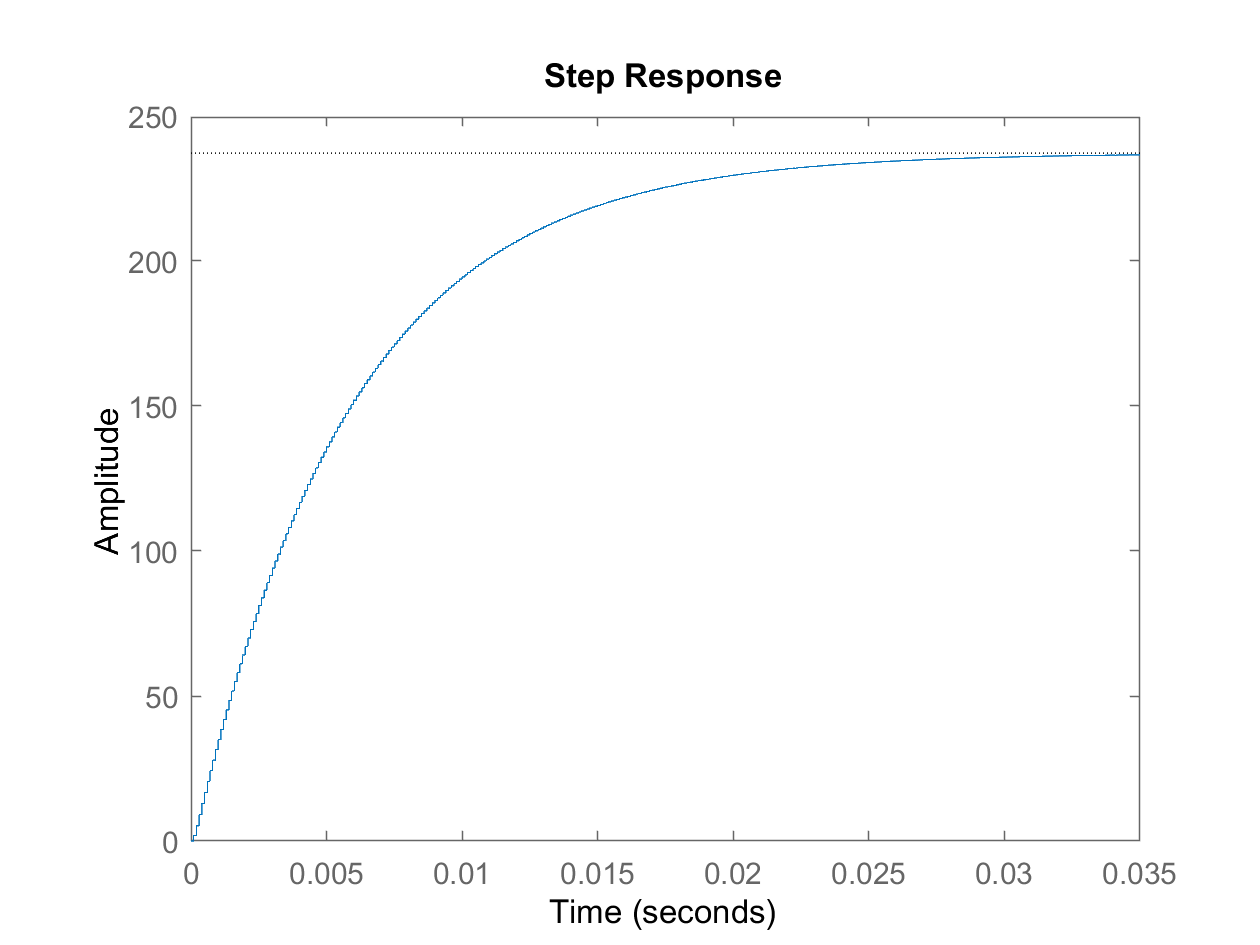


step(sistema_z*261);

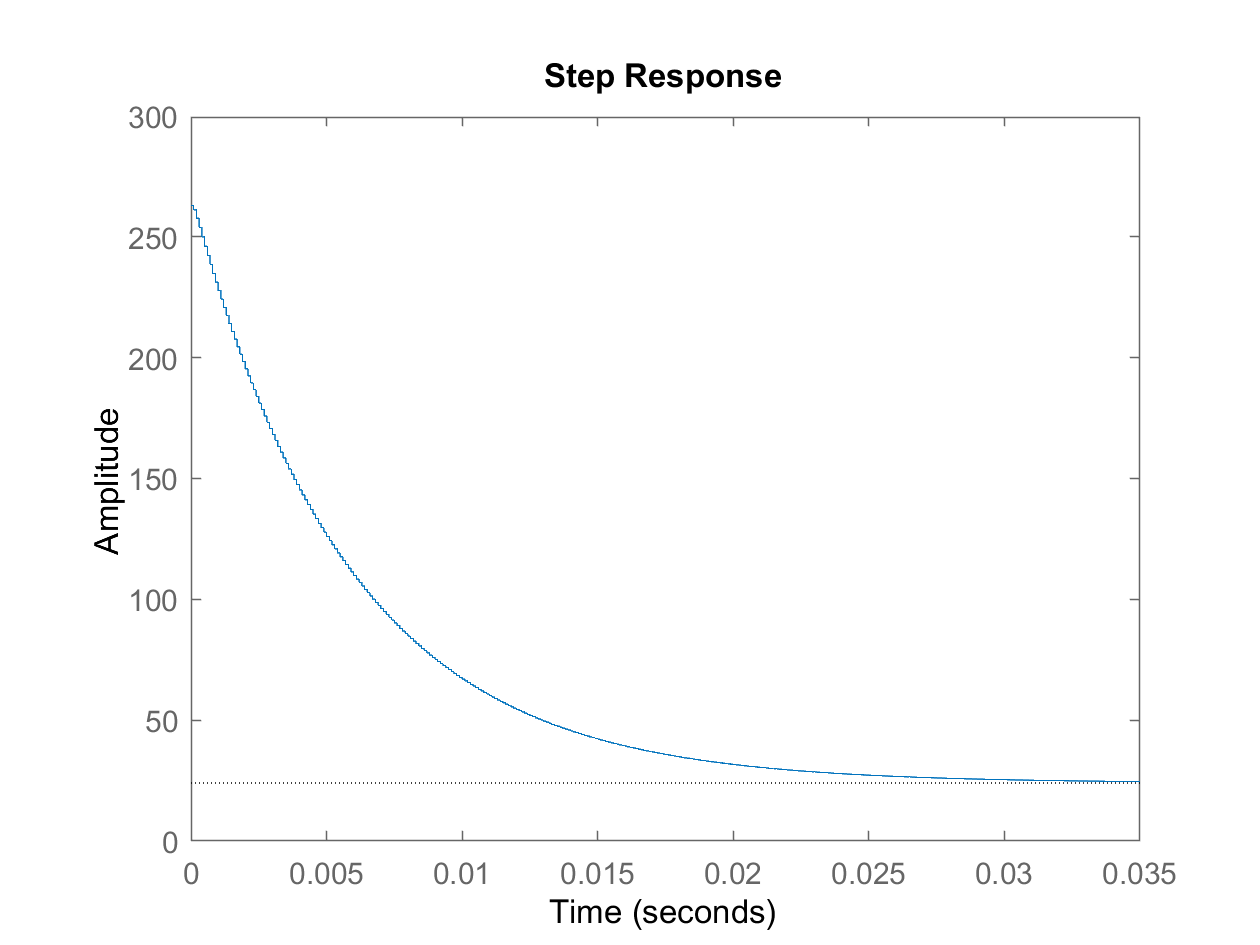

sistema2= Control_z/(1+Control_z*F_z);
step(sistema2*263);

F_z.Denominator{1}

ans =     1.0000   -1.2576    0.2588
